### 1 设置对应参数

%% 以下参数是自己设置的
frame_index  = 1;  % 设置想解析的帧的序号
tx_index     = 1;  % 设置想解析的发射天线的序号
n_angle_bins = 64; % 设置想计算的angle bins点数

%% 以下参数是根据cfg配置文件填入的
n_chirps  = 64;    % 对应profileCfg中第 8 个参数
n_rx      = 4;     % 对应channelCfg中第 1 个参数
n_tx      = 2;     % 对应channelCfg中第 2 个参数
n_samples = 256;   % 对应profileCfg中第 10个参数

startFreq            = 77e12;     %Hz   对应profileCfg中第 2 个参数
idleTime             = 25e-6;     %s    对应profileCfg中第 3 个参数
adc_valid_start_time = 7e-6;      %s    对应profileCfg中第 4 个参数
rampEndTime          = 48.96e-6;  %s    对应profileCfg中第 5 个参数
freq_slope           = 81.699e12; %Hz/s 对应profileCfg中第 8 个参数
sample_rate          = 12.5e6;    %Hz   对应profileCfg中第 11个参数

%% 以下参数是根据上述参数计算的
midFreq = startFreq*1e-3+(adc_valid_start_time+n_samples/sample_rate/2)*freq_slope; % Hz
chirp_repetition_period = (idleTime+rampEndTime)*n_tx;       % s

maxRange = (3e8 * sample_rate) / (2 * freq_slope);           % m
maxVelocity = 3e8 / (4 * midFreq * chirp_repetition_period); % m/s

%% 以下变量用于绘图时显示坐标轴的物理含义值的标签
range_label   = round(linspace(0           ,maxRange   ,n_samples   ),2);
doppler_label = round(linspace(-maxVelocity,maxVelocity,n_chirps    ),2);
angle_label   = round(linspace(-90         ,90         ,n_angle_bins),2);

### 2 载入保存的bin原始ADC数据

[filename,pathname] = uigetfile('*.bin');
fileID = fopen([pathname,filename],'r');
tic
raw_data = fread(fileID,'int16=>single');
toc

Elapsed time is 0.702010 seconds.


fclose(fileID);

### 3 根据参数解析重构数据格式

#### 3.1 reshape+permute

adc_data = reshape(raw_data,2,2,n_samples/2,n_rx,n_tx,n_chirps,[]);
size(adc_data)% 2Samples*2IQ(Lanes)*128(Samples/2)*4rx*2tx*64Chirps*300Frames

ans =      2     2   128     4     2    64   300


adc_data = permute(adc_data,[2,1,3,4,5,6,7]);
size(adc_data)% 2IQ(Lanes)*2Samples*128(Samples/2)*4rx*2tx*64Chirps*300Frames

ans =      2     2   128     4     2    64   300


adc_data = reshape(adc_data,2,n_samples,n_rx,n_tx,n_chirps,[]);
size(adc_data)% 2IQ(Lanes)*256Samples*4rx*2tx*64Chirps*300Frames

ans =      2   256     4     2    64   300


adc_data = squeeze(complex(adc_data(2,:,:,:,:,:),adc_data(1,:,:,:,:,:)));
size(adc_data)% 复数256Samples*4rx*2tx*64Chirps*300Frames

ans =    256     4     2    64   300


% adc_data_2d = reshape(adc_data(:,:,1:2,:,:),n_samples,n_rx*2,n_chirps,[]);
% whos adc_data_2d % 复数256Samples*8VirtualAnts*64Chirps*300Frames

**得到的adc_data格式为：**

   256   x      4      x      2      x   64   x 300

采样点 x RX天线 x TX天线 x Chirp x 帧

**得到的adc_data_2d格式为：**

   256   x           8           x   64   x 300

采样点 x 虚拟天线通道 x Chirp x 帧

#### 3.2 清除不用的变量

clearvars raw_data ans fileID;

### 4 绘制时域IQ波形

选取第1个接收天线、第tx_index个发射天线、第1个chirp、第frame_index帧的256个采样点

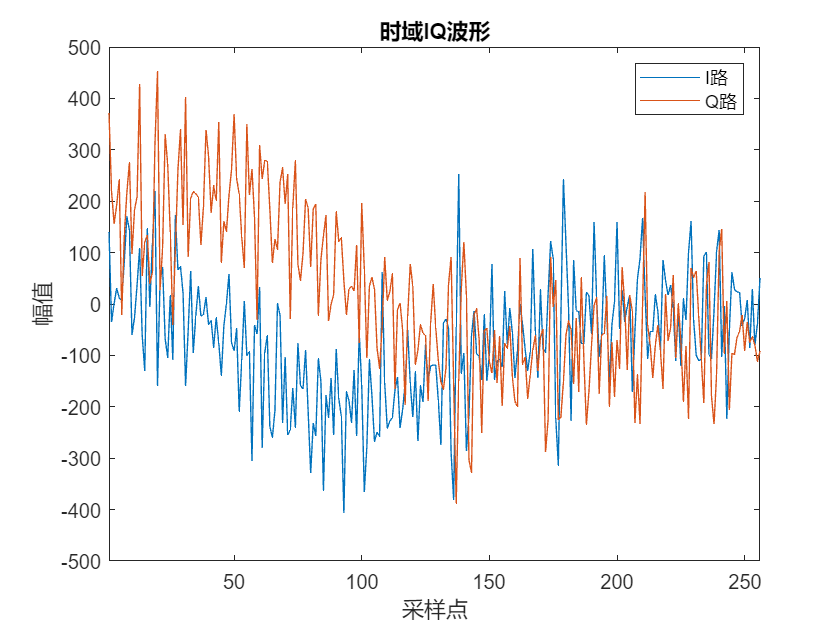

figure
plot(real(squeeze(adc_data(:,1,tx_index,1,frame_index)))) %I路
hold on
plot(imag(squeeze(adc_data(:,1,tx_index,1,frame_index)))) %Q路
hold off
xlim([1,n_samples])
title("时域IQ波形")
xlabel("采样点")
ylabel("幅值")
legend("I路","Q路")

### 5 计算Range-FFT

沿sample轴计算n_samples点DFT（对每帧每虚拟通道每chirp的n个采样点做DFT，点数为采样点数n_samples）

**将adc_data_2d：**

   256   x      4      x      2      x   64   x 300

采样点 x RX天线 x TX天线 x Chirp x 帧

**变为range_fft：**

   256   x      4      x      2      x   64   x 300

距离维 x RX天线 x TX天线 x Chirp x 帧

（对快时间维度处理）

#### 5.1 一维FFT

range_fft = fft(adc_data,[],1);

#### 5.2 静态杂波滤除

**5.2.1 MTI 算法**

两脉冲对消，也称一次对消

静止目标的相位不会发生变化，而运动目标的相位与静止目标不同

因此相邻两个脉冲做差会把相同的相位值减掉，留下的就是运动目标的相位，从而达到**滤除静止目标**的功能

% range_fft_MTI = cat(4,range_fft(:,:,:,1,:),range_fft);    % 延后一个chirp
% range_fft_MTI = range_fft-range_fft_MTI(:,:,:,1:end-1,:); % 前后相消

其中信号的直流分量部分得到了良好的抑制，但同时目标的幅值也受到了同样的影响，因为在一次对消过程中，相邻的脉冲相减其实除了相位得到了消除，还有“复数绝对值”的削弱。另外，MTI由于仅对零速通道附近的信号“陷波”，而对于高速通道保持不变，因此得到的结果中背景噪声显得非常杂乱。MTI仅仅是抑制了静态目标的相位，**对于微动目标不友好**。

**5.2.2 相量均值相消算法**

相量均值相消算法通过求均值，在**抑制静止目标**相位的同时极大**提高了动目标**或者**微动目标**的信噪比

range_fft_avg = repmat(mean(range_fft,4),[1,1,1,n_chirps,1]); % 沿chirp计算均值
range_fft_avg = range_fft-range_fft_avg;                             % 与均值相消

#### 5.3 绘制Range-FFT图

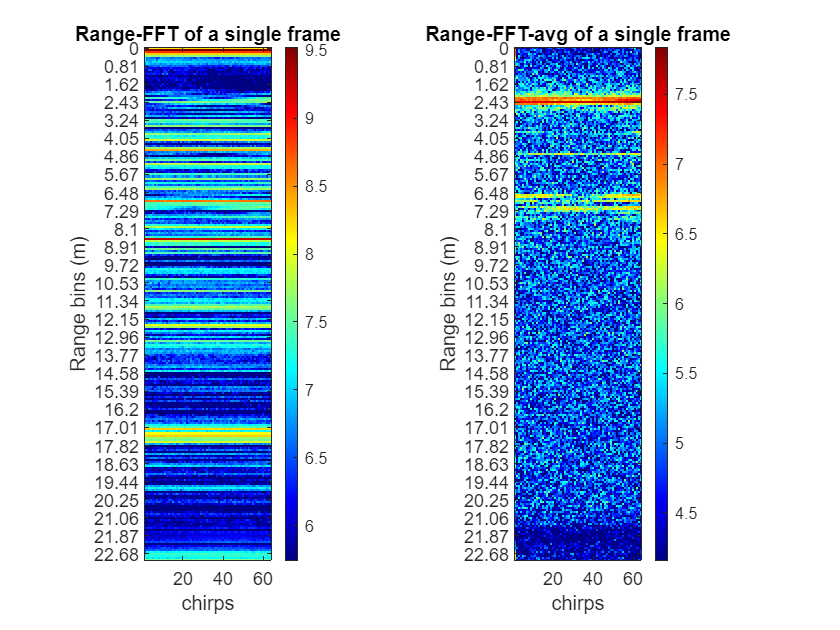

% 无相量均值相消算法
figure
subplot(1,2,1)
imagesc(log(abs(squeeze(mean(range_fft(:,:,tx_index,:,frame_index),2)))))

colorbar
colormap(jet)
lims=clim;
clim([lims(2)-(lims(2)-lims(1))*0.5,lims(2)]);
axis equal
xlim([1,n_chirps])
yticks(1:9:n_samples)
yticklabels(range_label(1:9:n_samples))
title("Range-FFT of a single frame")
xlabel("chirps")
ylabel("Range bins (m)")

% 有相量均值相消算法
subplot(1,2,2)
imagesc(log(abs(squeeze(mean(range_fft_avg(:,:,tx_index,:,frame_index),2)))))

colorbar
colormap(jet)
lims=clim;
clim([lims(2)-(lims(2)-lims(1))*0.5,lims(2)]);
axis equal
xlim([1,n_chirps])
yticks(1:9:n_samples)
yticklabels(range_label(1:9:n_samples))
title("Range-FFT-avg of a single frame")
xlabel("chirps")
ylabel("Range bins (m)")

### 6 计算Doppler-FFT

沿chirp轴计算n_chirps点DFT（对每帧每虚拟通道每采样点的n个chirp做DFT，点数为chirp数n_chirps）

**将range_fft：**

   256   x      4      x      2      x   64   x 300

距离维 x RX天线 x TX天线 x Chirp x 帧

**变为doppler_fft：**

   256   x      4      x      2      x    64    x 300

距离维 x RX天线 x TX天线 x 多普勒 x 帧

（对慢时间维度处理）

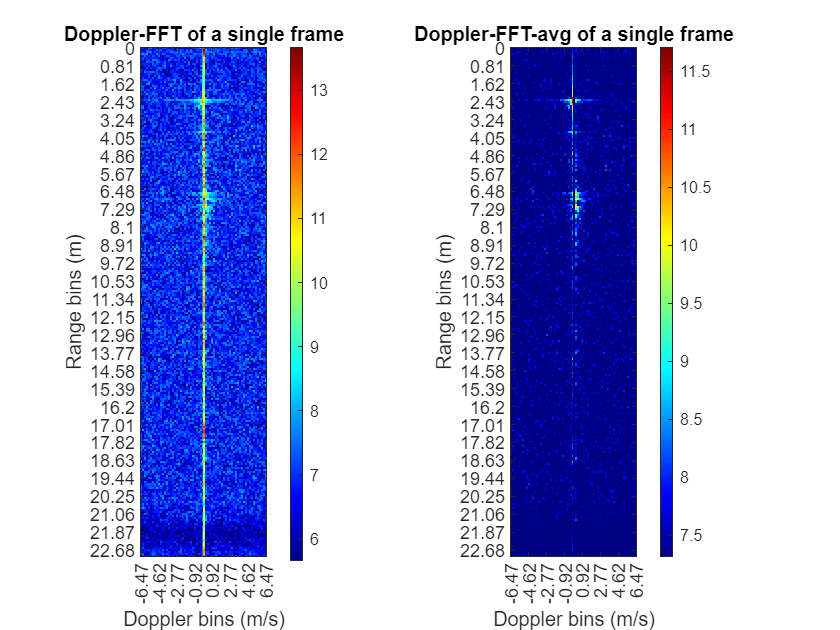

% 无相量均值相消算法
doppler_fft = fft(range_fft,[],4);
doppler_fft = fftshift(doppler_fft,4);

figure
subplot(1,2,1)
imagesc(log(abs(squeeze(mean(doppler_fft(:,:,tx_index,:,frame_index),2)))))

colorbar
colormap(jet)
lims=clim;
clim([lims(2)-(lims(2)-lims(1))*0.65,lims(2)]);
axis equal
xlim([1,n_chirps])
xticks(1:9:n_chirps)
xticklabels(doppler_label(1:9:n_chirps))
yticks(1:9:n_samples)
yticklabels(range_label(1:9:n_samples))
title("Doppler-FFT of a single frame")
xlabel("Doppler bins (m/s)")
ylabel("Range bins (m)")

% 有相量均值相消算法
doppler_fft_avg = fft(range_fft_avg,[],4);
doppler_fft_avg = fftshift(doppler_fft_avg,4);

subplot(1,2,2)
imagesc(log(abs(squeeze(mean(doppler_fft_avg(:,:,tx_index,:,frame_index),2)))))

colorbar
colormap(jet)
lims=clim;
clim([lims(2)-(lims(2)-lims(1))*0.22,lims(2)]);
axis equal
xlim([1,n_chirps])
xticks(1:9:n_chirps)
xticklabels(doppler_label(1:9:n_chirps))
yticks(1:9:n_samples)
yticklabels(range_label(1:9:n_samples))
title("Doppler-FFT-avg of a single frame")
xlabel("Doppler bins (m/s)")
ylabel("Range bins (m)")

### 7 1D-CA-CFAR Detector on Range-FFT

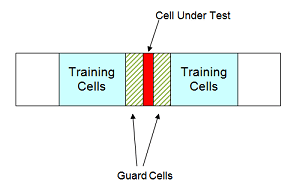

In this detector we use 8 training cells and 4 guard cells in total. 

This means that there are 4 training cells and 2 guard cell on each side of the CUT.

Assuming the desired false alarm rate is 1e-4.

range_cfar_1d = phased.CFARDetector('NumTrainingCells',8,'NumGuardCells',4);
range_cfar_1d.Method = "CA"; % Cell-averaging CFAR
range_cfar_1d.ThresholdFactor = 'Auto';
range_cfar_1d.ProbabilityFalseAlarm = 1e-4;
range_cfar_1d.OutputFormat = "CUT result"; % for visualization only

range_fft_tmp = abs(reshape(mean(range_fft_avg(:,:,tx_index,:,:),2),n_samples,[])).^2;% 对接收天线做平均并取信号幅值的平方

tic
range_detected = range_cfar_1d(range_fft_tmp,1:n_samples);
toc

Elapsed time is 0.660579 seconds.


range_detected = reshape(range_detected,n_samples,n_chirps,[]);

release(range_cfar_1d);

CFAR visualization

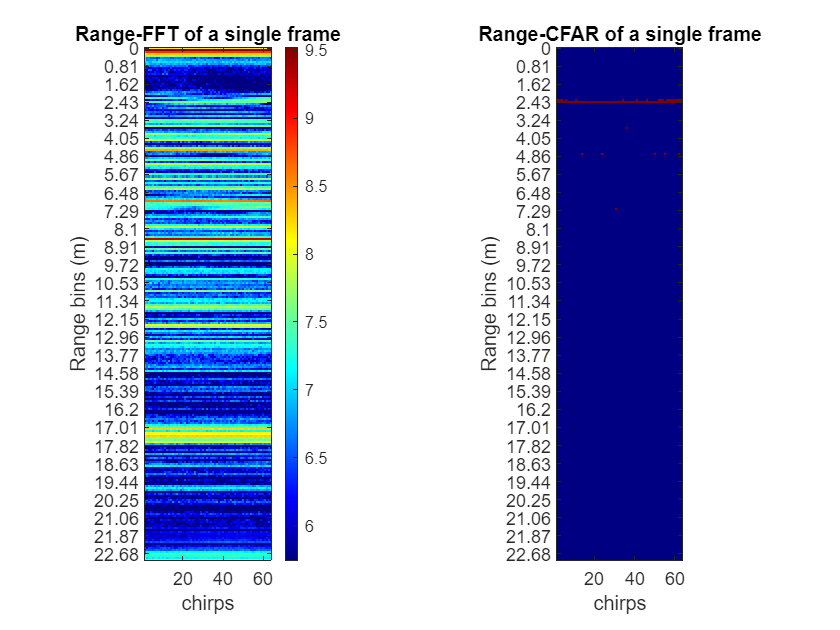

figure
subplot(1,2,1)
imagesc(log(abs(squeeze(mean(range_fft(:,:,tx_index,:,frame_index),2)))))

colorbar
colormap(jet)
lims=clim;
clim([lims(2)-(lims(2)-lims(1))*0.5,lims(2)]);
axis equal
xlim([1,n_chirps])
yticks(1:9:n_samples)
yticklabels(range_label(1:9:n_samples))
title("Range-FFT of a single frame")
xlabel("chirps")
ylabel("Range bins (m)")

subplot(1,2,2)
imagesc(squeeze(range_detected(:,:,1)))
axis equal
xlim([1,n_chirps])
yticks(1:9:n_samples)
yticklabels(range_label(1:9:n_samples))
title("Range-CFAR of a single frame")
xlabel("chirps")
ylabel("Range bins (m)")

### 8 2D-CFAR Detector on Range-Doppler Matrix

TBD

#### 8.1 设置参考单元和保护单元

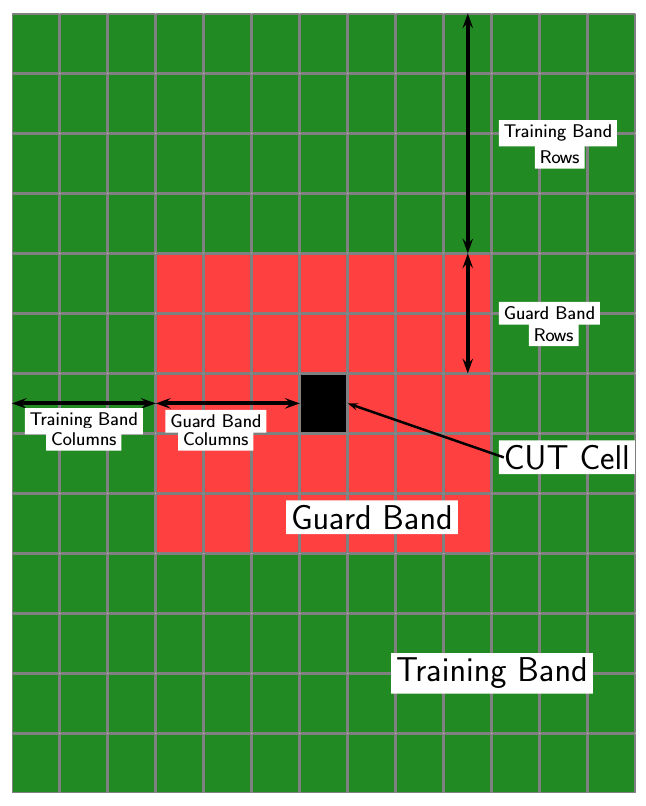

### 9 Doppler compensation on Range-FFT

TBD

### 10 计算Azimuth-FFT

沿virtual ants轴计算点DFT（对n_rx*n_tx个虚拟天线通道做DFT，点数为n_angle_bins）

**将doppler_fft：**

   256   x      4      x      2      x   64     x 300

距离维 x RX天线 x TX天线 x 多普勒 x 帧

**合并天线形成8个通道：**

   256   x           8           x   64   x 300

距离维 x 虚拟天线通道 x Chirp x 帧

**对8个通道做fft变为azimuth_fft：**

   256   x    64    x     64    x 300

距离维 x 角度维 x 多普勒 x 帧

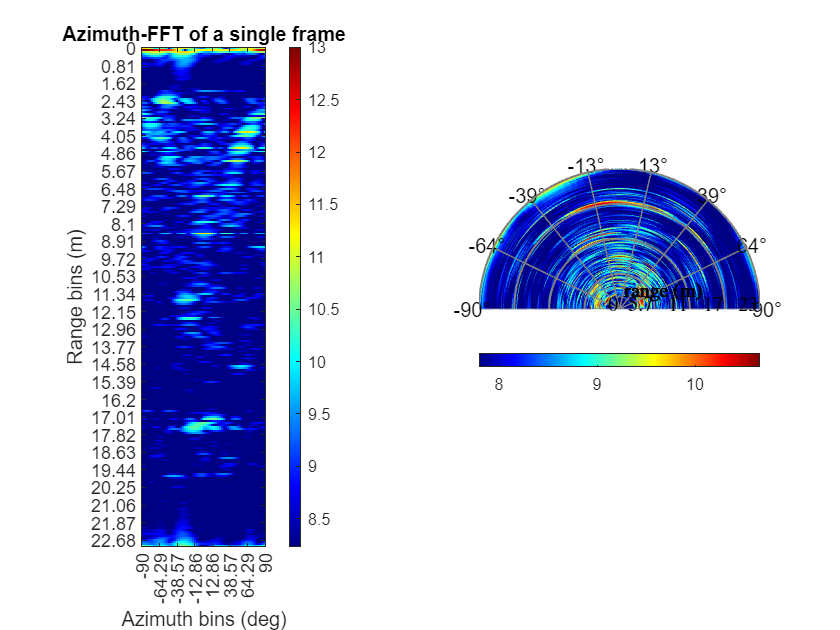

azimuth_fft = reshape(doppler_fft,n_samples,n_rx*n_tx,n_chirps,[]);
azimuth_fft = fft(azimuth_fft(:,:,:,frame_index),n_angle_bins,2);
azimuth_fft = fftshift(azimuth_fft,2);

% 生成range-azimuth图像
range_azimuth_img=log(abs(squeeze(mean(azimuth_fft(:,:,:,frame_index),3))));

figure
% 直角坐标平面图
subplot(1,2,1)
imagesc(range_azimuth_img)

colorbar
colormap(jet)
lims=clim;
clim([lims(2)-(lims(2)-lims(1))*0.45,lims(2)]);
axis equal
xlim([1,n_angle_bins])
xticks(1:9:n_angle_bins)
xticklabels(angle_label(1:9:n_angle_bins))
yticks(1:9:n_samples)
yticklabels(range_label(1:9:n_samples))
title("Azimuth-FFT of a single frame")
xlabel("Azimuth bins (deg)")
ylabel("Range bins (m)")

% 极坐标扇扫图
subplot(1,2,2)
Az = linspace(-90,90,n_angle_bins); % in degrees
R = linspace(0,maxRange,n_samples); % (distance in m)

[~,c]= polarPcolor(R,Az,range_azimuth_img,'labelR','range (m)');
set(c,'location','SouthOutside');
colormap(jet)
lims=clim;
clim([lims(2)-(lims(2)-lims(1))*0.6,lims(2)]);

### 11 DBSCAN聚类

TBD